# 微分器とノイズの関係

## 背景

現実世界の物理システムでは、ノイズを含まないシステムは存在しない。制御理論としては、ノイズは外乱の一種として考慮する。ノイズを含む物理システムを制御する場合、センサー計測値には必ずノイズが重畳され、その信号を受け取る制御器は影響を受け、制御性能が悪化する。ここでは、ノイズがPID制御器に与える影響と、その対処方法について説明する。

## ホワイトノイズ

ノイズには様々な種類があるが、ここでは最も一般的な「ホワイトノイズ」について考える。ホワイトノイズは、全ての周波数で同じスペクトル強度となるノイズである。

ホワイトノイズは、実用上は正規分布乱数で表現してもよい。Fig.1にその正規分布乱数を示す。横軸は秒である。

ts = 1e-6;
time = (0:ts:1)';
sample_n = numel(time);
randData = randn(sample_n, 1);

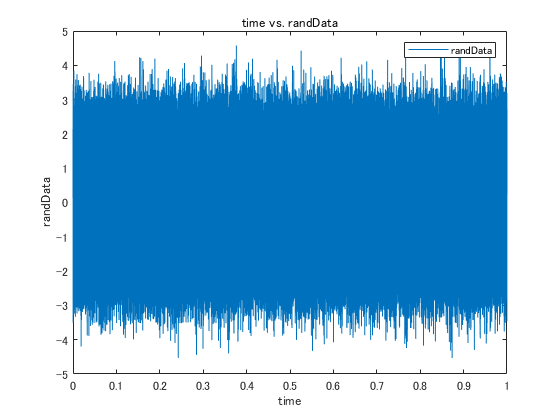

% 作成 time と randData の plot
fig_1 = plot(time,randData,'DisplayName','randData');

% xlabel, ylabel, title および legend の追加
xlabel('time')
ylabel('randData')
title('time vs. randData')
legend

Fig.1 ホワイトノイズ（時系列）

ここで、高速フーリエ変換を行い、ホワイトノイズの周波数スペクトルをプロットする。Fig.2のように、全ての周波数で同程度のスペクトルが存在することが分かる。横軸はHzである。

Y = fft(randData);
P2 = abs(Y/sample_n);
L = round(sample_n/2);
P1 = P2(1:L);
P1(2:end-1) = 2*P1(2:end-1);
freqData = (1/ts)*(1:L)/(2*L);

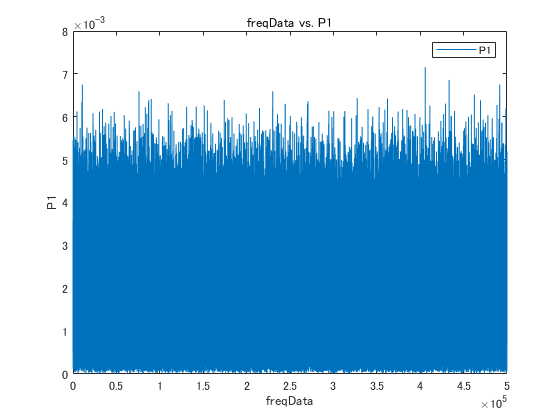

% 作成 freqData と P1 の plot
fig_2 = plot(freqData,P1,'DisplayName','P1');

% xlabel, ylabel, title および legend の追加
xlabel('freqData')
ylabel('P1')
title('freqData vs. P1')
legend

Fig.2 ホワイトノイズ（周波数）

## ホワイトノイズの影響

ここで、ホワイトノイズがPID制御器に与える影響について考察する。前セクションで確認したように、ホワイトノイズは全ての周波数領域で同程度の強度を持つため、eq.1のように表現することができる。


$$W=A_1 \sin \omega_1 t+A_2 \sin \omega_2 t+\cdots +A_n \sin \omega_n t=\sum_{k=1}^n A_k \sin \omega_k t\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 1\right)$$


ただし、$W$はホワイトノイズ、$A_k$は任意の振幅、$\omega_k$は任意の周波数とする。

$A_k$は極端に大きく外れた値は取らないものとする。話を簡単化するために、$A_k$はすべて同じ振幅とする。また、$\omega_k$は添え字が増加するに従って単調増加する周波数の数列とする。

このとき、比例器に入力されたホワイトノイズの出力$W_P$は、eq.2のようになる。


$$W_P =PA_1 \sin \omega_1 t+PA_2 \sin \omega_2 t+\cdots +PA_n \sin \omega_n t\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 2\right)$$


ただし、$P$は比例ゲインである。比例器は、入力を定数倍するだけであるので、ホワイトノイズの特性は変化していない。

次に、積分器に入力された場合を考える。ホワイトノイズの出力$W_I$は、eq.3のようになる。


$$W_I =I\int \left(A_1 \sin \omega_1 t+A_2 \sin \omega_2 t+\cdots +A_n \sin \omega_n t\right)\textrm{dt}$$



$$W_I =-I\frac{A_1 }{\omega_1 }\cos \omega_1 t-I\frac{A_2 }{\omega_2 }\sin \omega_2 t-\cdots -I\frac{A_n }{\omega_n }\cos \omega_n t+C\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 3\right)$$


ただし、$I$は積分ゲイン、$C$は不定積分の定数である。一般的に、制御器が制御する物理モデルは1[Hz]以上の周波数の領域で動作する。従って、$\omega_k$は1より大きい実数値となる。このことから、添え字の数値が大きくなるにつれて、つまり高周波になるにつれて、各項のゲインが減少していくことがわかる。

次に、微分器に入力された場合を考える。ホワイトノイズの出力$W_D$は、eq.4のようになる。


$$W_D =D\frac{d}{\textrm{dt}}\left(A_1 \sin \omega_1 t+A_2 \sin \omega_2 t+\cdots +A_n \sin \omega_n t\right)$$



$$W_D =DA_1 \omega_1 \cos \omega_1 t+DA_2 \omega_2 \cos \omega_2 t+\cdots +DA_n \omega_n \cos \omega_n t\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 4\right)$$


ただし、$D$は微分ゲインである。積分器の場合と比べると、こちらは高周波になるにつれてゲインが増加していくことがわかる。

ホワイトノイズは全ての周波数成分を含むことから、連続時間では無限に周波数の項が存在する。その場合、小さなノイズでも微分器があれば無限大に大きくなるということになる。ただし現実には、連続時間で理想的に動作する微分器は存在せず、また、PID制御が計算されるシステムは離散時間で動作する。よって、サンプリング周波数がノイズの周波数の上限となり、ノイズの振幅が無限大に増幅されることはない。それでも、元々の物理システムの信号の変化に対して、ノイズの振幅が無視できない比率で存在する場合は、対策を行う必要がある。

## 不完全微分器

前セクションで確認したように、ノイズは微分器にて増幅されるので、微分器に対してノイズ対策を行う。対策法としては、ローパスフィルタが有効である。

ここで、diff_tfを微分の伝達関数、LPF_tfをローパスフィルタの伝達関数としてボード線図で比較してみる。ローパスフィルタは簡易的に、1次遅れのシンプルなものを用いた。

diff_tf = tf([1, 0], 1)

diff_tf =
 
  s
 
連続時間の伝達関数です。



LPF_tf = tf(1, [1, 1])

LPF_tf =
 
    1
  -----
  s + 1
 
連続時間の伝達関数です。



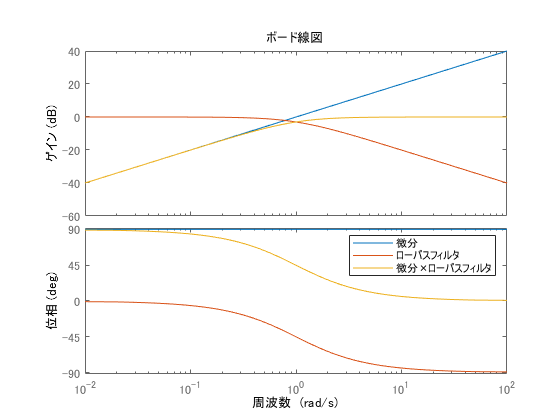

bode(diff_tf, LPF_tf, diff_tf*LPF_tf);
legend('微分', 'ローパスフィルタ', '微分×ローパスフィルタ');

Fig.3 微分とローパスフィルタのボード線図

微分は、周波数の増加に合わせて単調にゲインが増加していくが、ローパスフィルタは、あるカットオフ周波数以降、ゲインが減少する。よって、この二つの伝達関数を直列接続することで、高周波領域のゲイン増加を抑えることができる。

理想的な微分器にローパスフィルタを組み合わせたものを不完全微分器と呼ぶ。不完全微分器の最もシンプルな表現方法としては、$\frac{N\;s}{s+N}$のように伝達関数を構成することである。$N$を調整することで、カットオフ周波数を調整することができる。

Simulink標準ライブラリの「PID Controller」ブロックには、デフォルトで不完全微分器を用いるようになっている。このブロックでは、計算の効率化のため、さらなる簡略化がなされている。'DFN_LPF_diff.slx'にて、その計算を表現した。モデルを開き、不完全微分器のブロック図を確認すること。

model_name = 'DFN_LPF_diff';
open_system(model_name);

ローパスフィルタを組み合わせていない、純粋な微分器を完全微分器と呼ぶ。

ステップ関数を入力させた結果を、理想的な微分器と比較してみる。モデルを実行し、動作を確認すること。

sim(model_name);
DFN_LPF_diff_plot_in_SDI;

Nを調整することで、ローパスフィルタのカットオフ周波数を調整することができる。Nを変更して再度モデルを実行し、不完全微分器の動作がどのように変化するか確認すること。

*Copyright 2021 The MathWorks, Inc.*